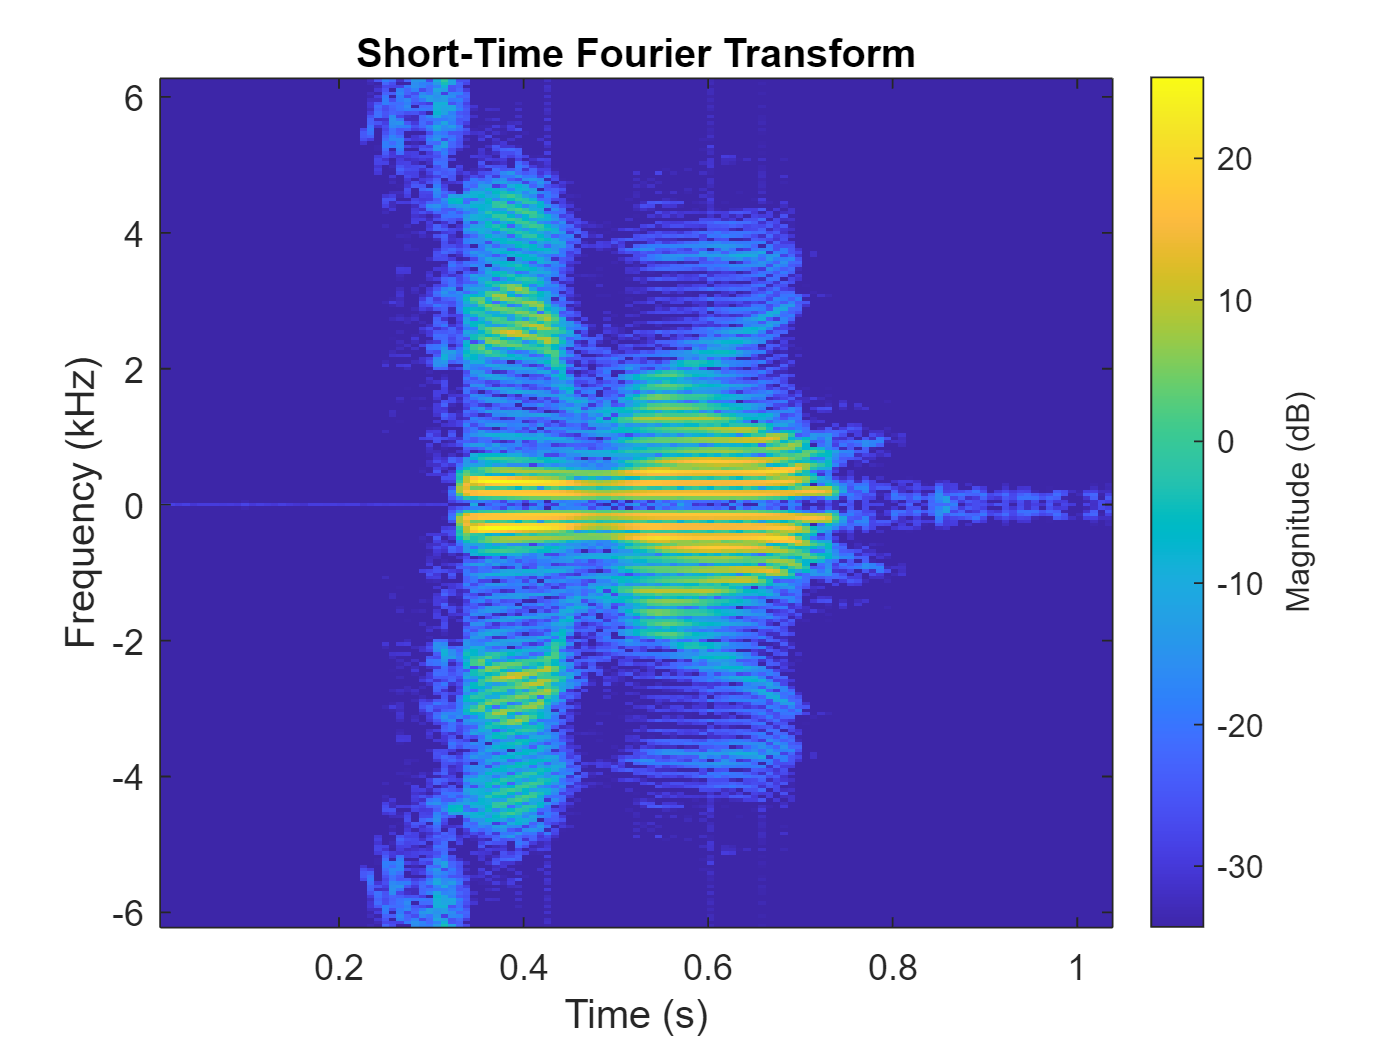

% s1
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s1.wav');
[S,F,T] = stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)

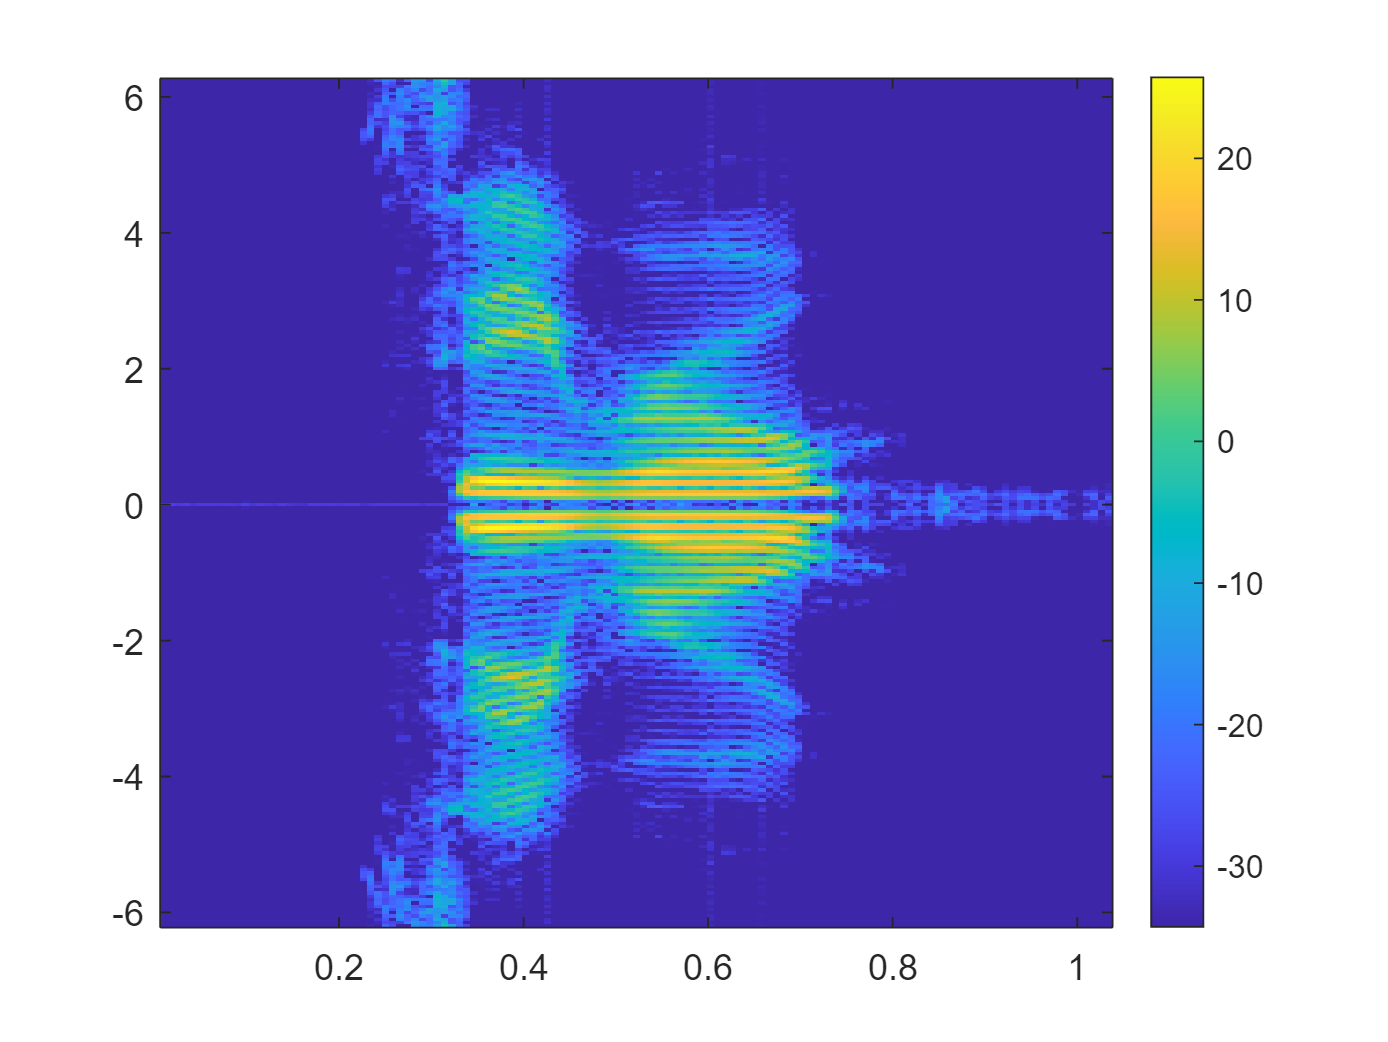

% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar

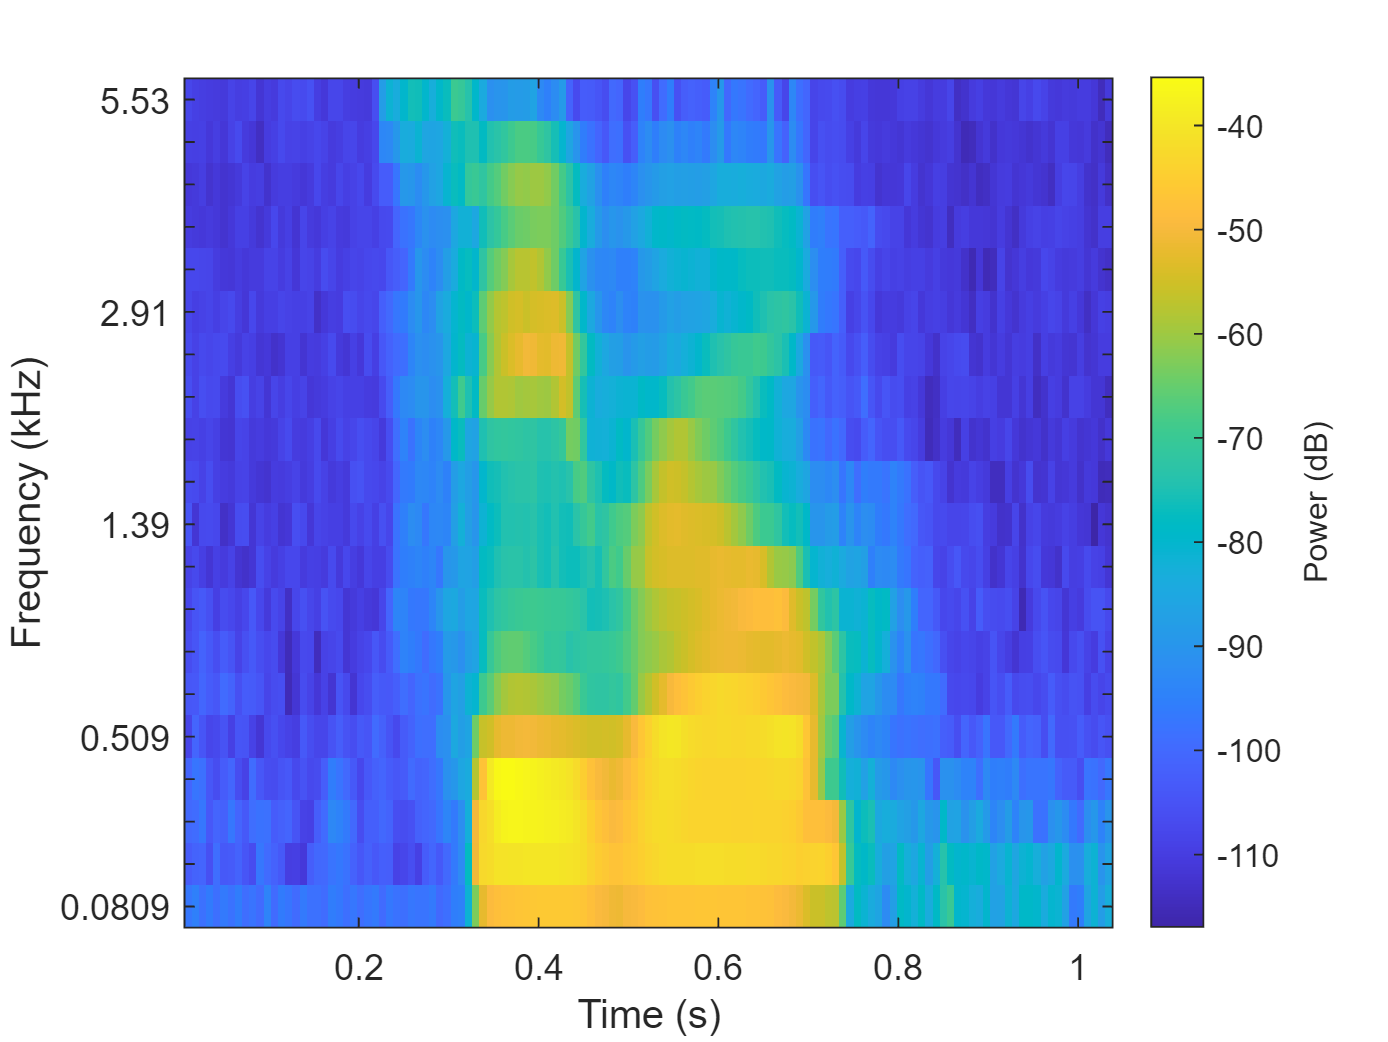

% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);

[Ss,Ff,Tt] = melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))

sdb1 =  -194.1206 -190.1952 -196.6388 -192.3785 -197.1323 -192.6350 -196.0287 -191.6611 -198.0770 -195.4475 -199.0470 -188.1122 -199.0369 -192.3006 -194.9345 -199.3409 -192.5457 -196.2993 -196.7321 -198.4479 -191.2308 -193.3914 -197.3069 -194.0801 -197.7448 -195.0029 -192.9975 -199.0232 -193.2634 -195.8156 -197.1752 -194.0203 -195.3581 -195.3880 -192.9020 -199.4768 -196.9419 -190.7919 -189.7137 -163.0235 -125.9040 -104.3596  -97.5326  -95.9556  -94.7257  -93.9840  -93.3135  -92.8340  -92.1050  -91.7046
 -205.4389 -202.3668 -201.5322 -211.4877 -198.0798 -206.4983 -205.8745 -202.3744 -208.5479 -213.4867 -194.1959 -199.3294 -202.9623 -207.0233 -219.4935 -218.6794 -222.2549 -204.7389 -200.4672 -199.8042 -195.2221 -193.5763 -195.7481 -202.6730 -208.0702 -203.8819 -207.3937 -203.9799 -205.0738 -217.6003 -215.7082 -212.1577 -218.3338 -205.3149 -200.9153 -207.1195 -199.6061 -193.0308 -185.4096 -155.2143 -101.0519  -85.3301  -83.9281  -81.2766  -81.2156  -80.8547  -80.5085  -80.1437  -79.8432  

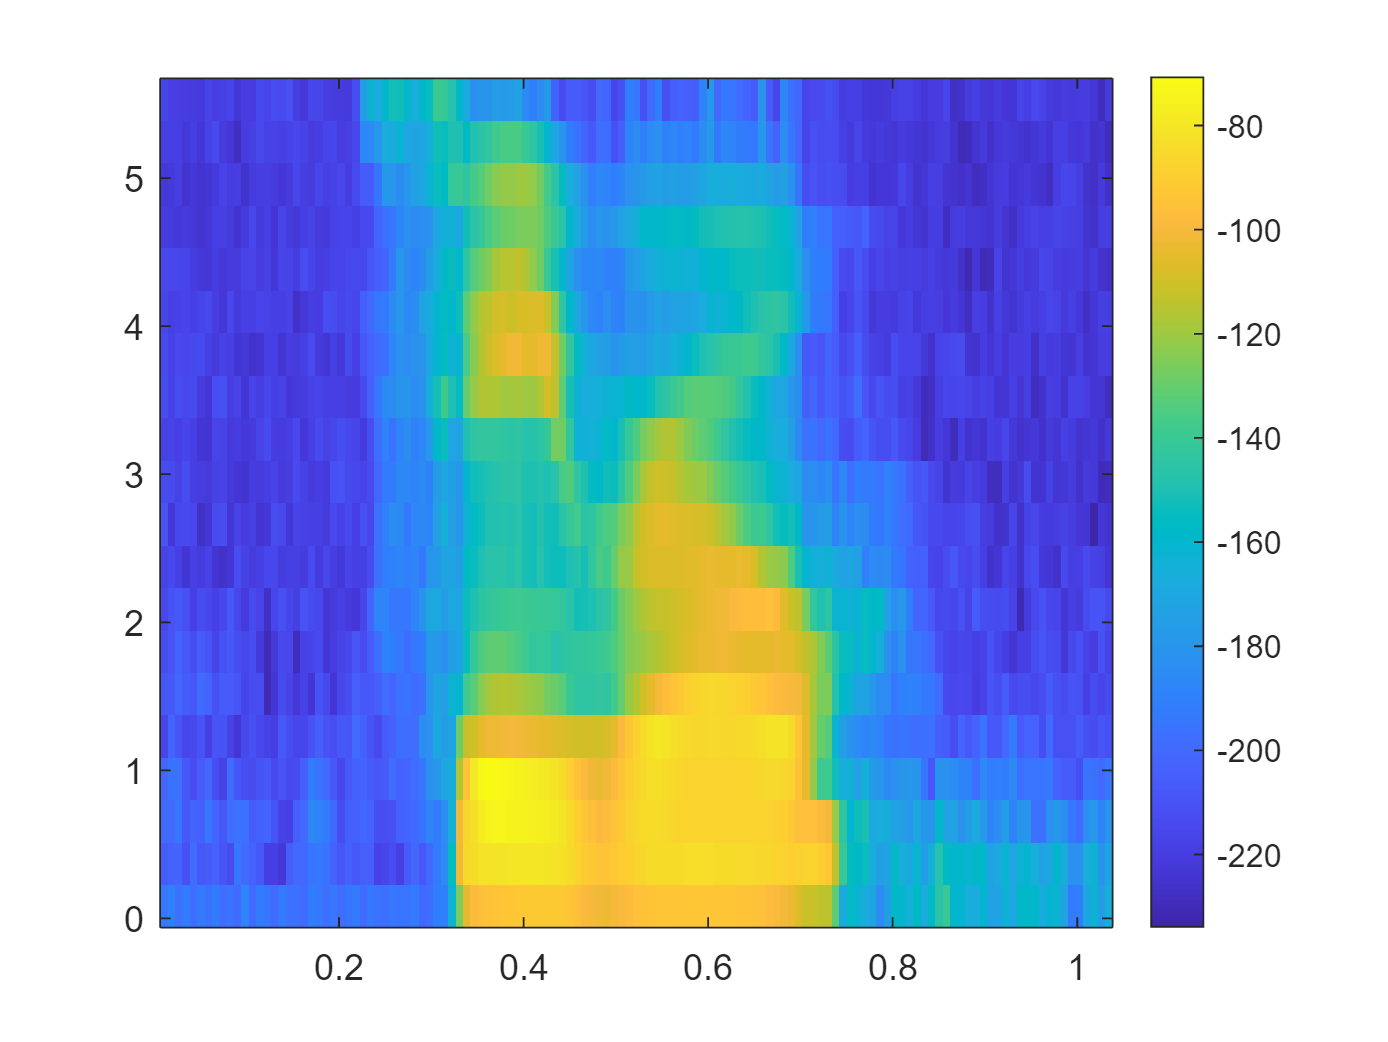

imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar

% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1))

bl =          0    1.6559  113.2620  128.0000


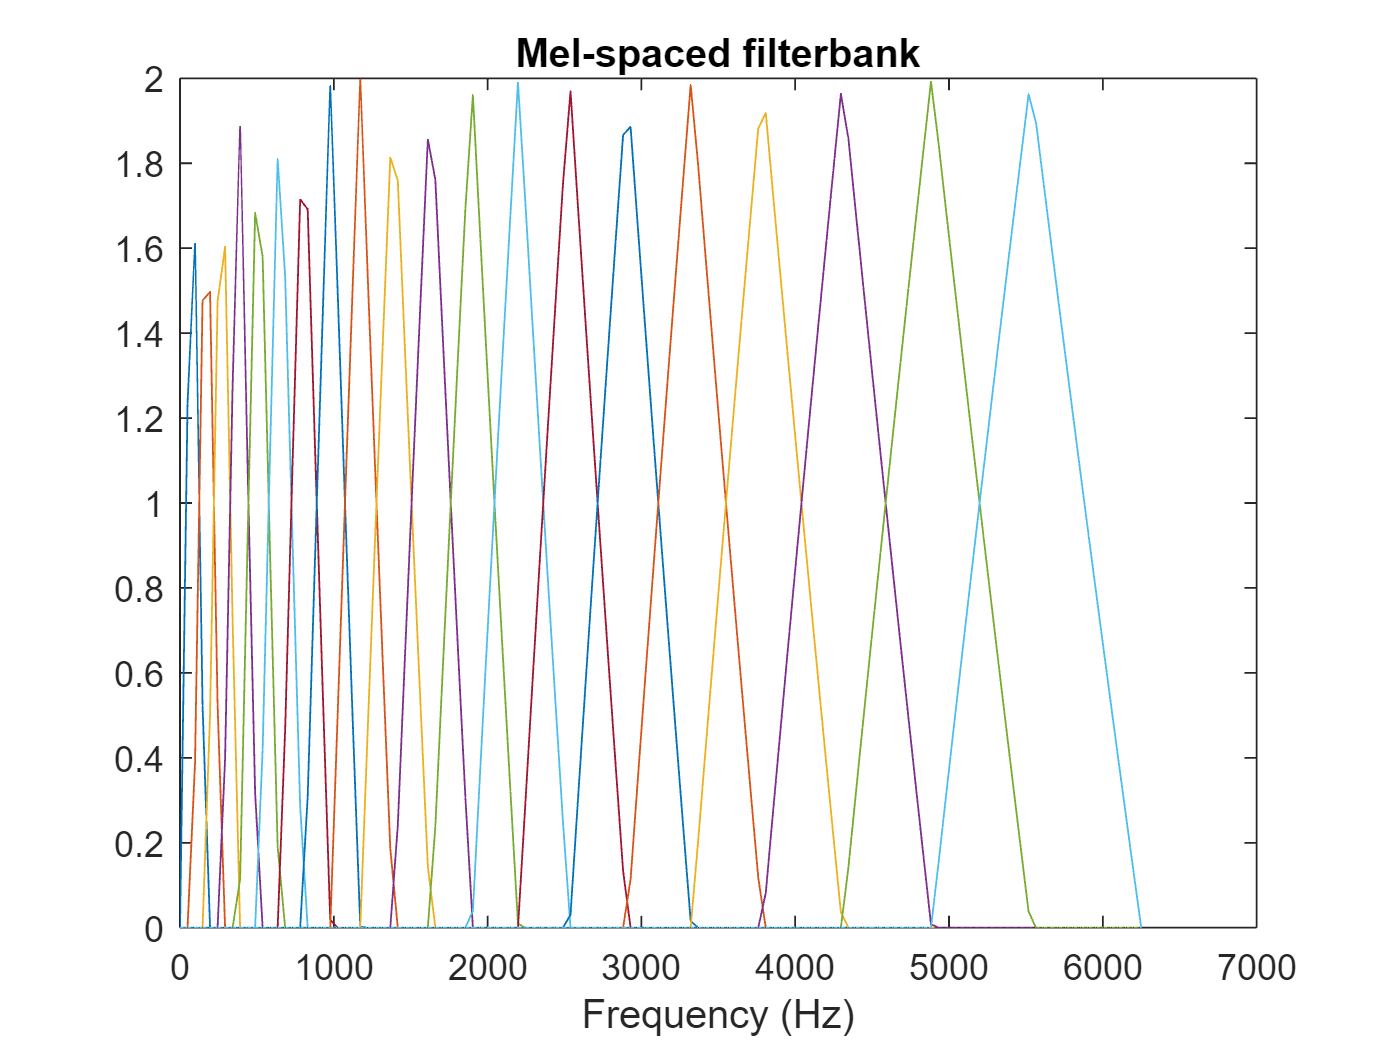


b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');

% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(n2-1:n)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some))

some =   -69.7171  -65.8067  -72.2741  -67.9403  -72.8501  -68.2293  -71.6313  -67.2984  -73.6761  -71.0123  -74.6664  -63.7016  -74.7099  -67.8782  -70.5032  -74.9071  -68.1170  -71.9128  -72.3204  -74.1070  -66.8224  -69.0731  -72.8576  -69.6450  -73.3907  -70.5675  -68.5878  -74.6012  -68.8713  -71.3933  -72.7578  -69.6236  -70.9330  -71.0339  -68.5129  -75.0485  -72.5220  -66.5058  -65.3298  -38.8945   -1.9646   19.5877   26.3963   27.9787   29.2092   29.9529   30.6214   31.1063   31.8370   32.2397
  -80.2057  -77.1129  -76.4217  -86.2889  -72.8690  -81.2576  -80.7000  -77.1309  -83.3891  -88.2929  -69.1080  -74.2157  -77.7803  -81.7957  -94.3398  -93.4874  -96.8992  -79.4723  -75.3453  -74.5951  -70.1895  -68.4301  -70.7212  -77.6106  -82.7939  -78.7854  -82.1661  -78.8720  -79.8998  -92.3376  -90.4023  -86.8048  -93.0183  -80.0793  -75.6714  -82.0854  -74.6394  -67.8350  -60.3091  -30.0204   24.0246   39.8031   41.2875   43.9238   44.0010   44.3663   44.7177   45.0824   45.3888  

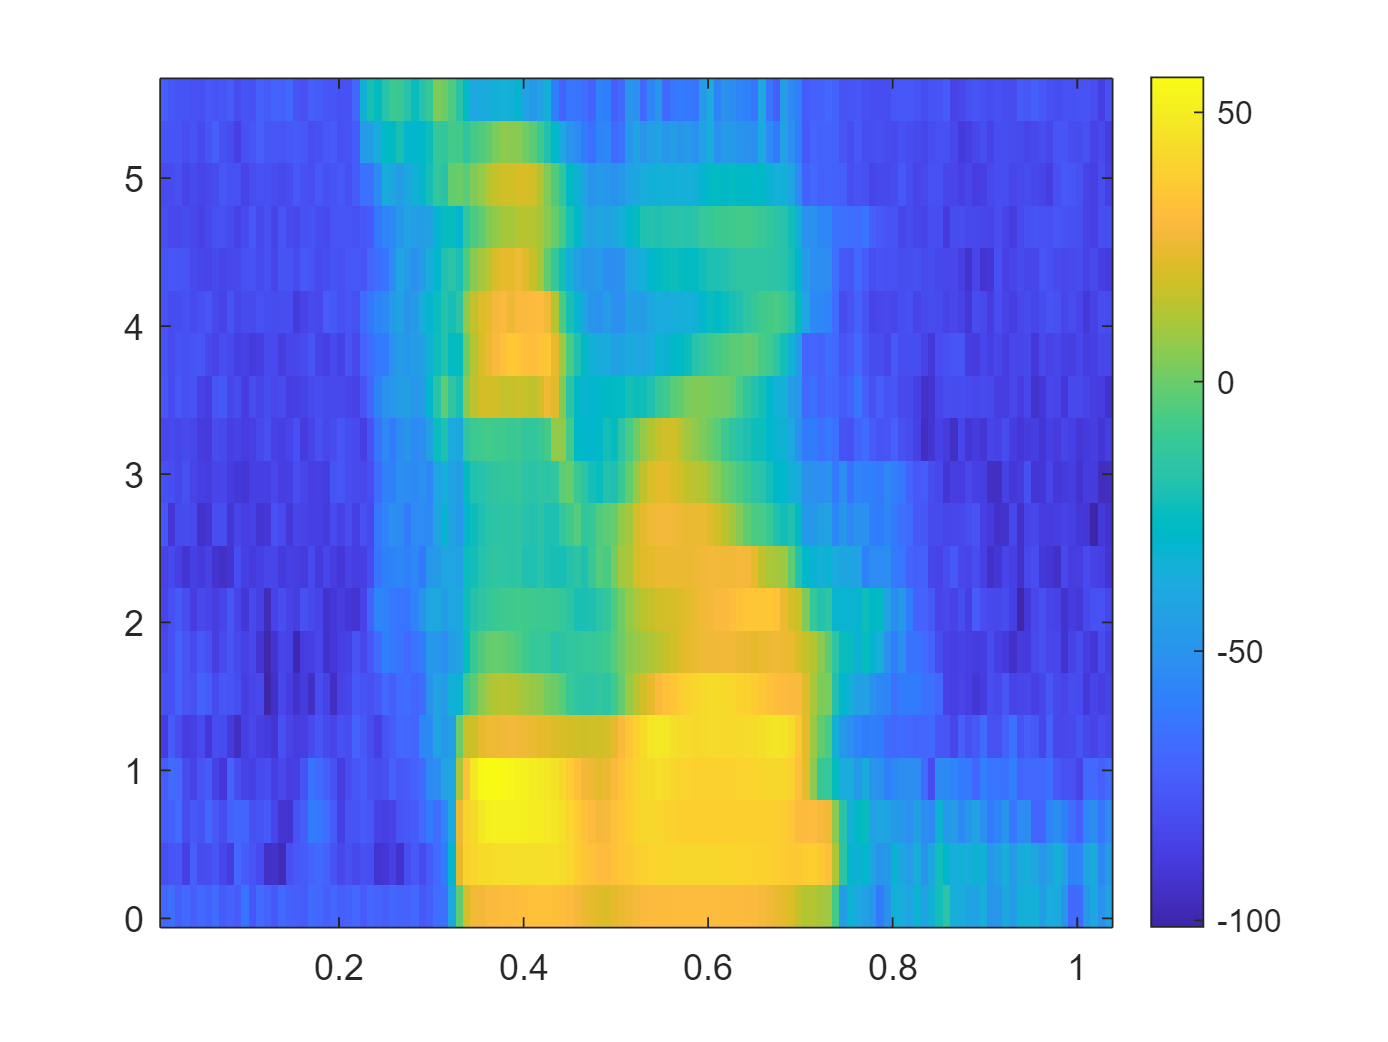

imagesc((T),(Ff/1000),some);
set(gca, 'YDir', 'normal');
view(2)
colorbar

% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(some(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
y = sdb - mean(sdb,'all')

y =    36.6283   36.5668   36.4809   36.8098   36.8639   36.9043   36.8841   36.8487   36.9002   36.8751   36.9840   37.0313   36.9732   36.9872   37.1547   37.1516   37.0028   37.0563   37.0738   36.9096   36.6286   36.6075   36.8370   36.8331   36.9375   36.7667   36.6223   36.0283   35.6189   34.9245   34.1720   33.8283   33.4287   33.5611   33.4380   32.9744   31.6324   29.8519   28.9884   28.0507   23.9656    6.8018    9.3724   16.4480   19.0782   20.5186   21.1455   20.9751   21.4375   19.7374
  -17.8079    7.0524    6.0976  -22.3944   -8.5356    5.7400    2.0453  -30.8813   -1.3784   -2.9160    5.7225    0.9925   -5.9347   -1.6605    9.7289    8.7648    5.4629    6.3560    2.0919  -39.9198    5.1707    7.4190   -3.5131    1.8386    5.0443   -4.4677   -8.4382   15.2980   17.4188   20.5175   21.9233   22.4022   23.3061   22.2858   21.3023   21.9453   21.5471   23.2743   23.4142   19.3674   14.9917   19.6764   20.0619   20.3945   20.0013   18.9291   18.3353   18.1354   17.3278   18

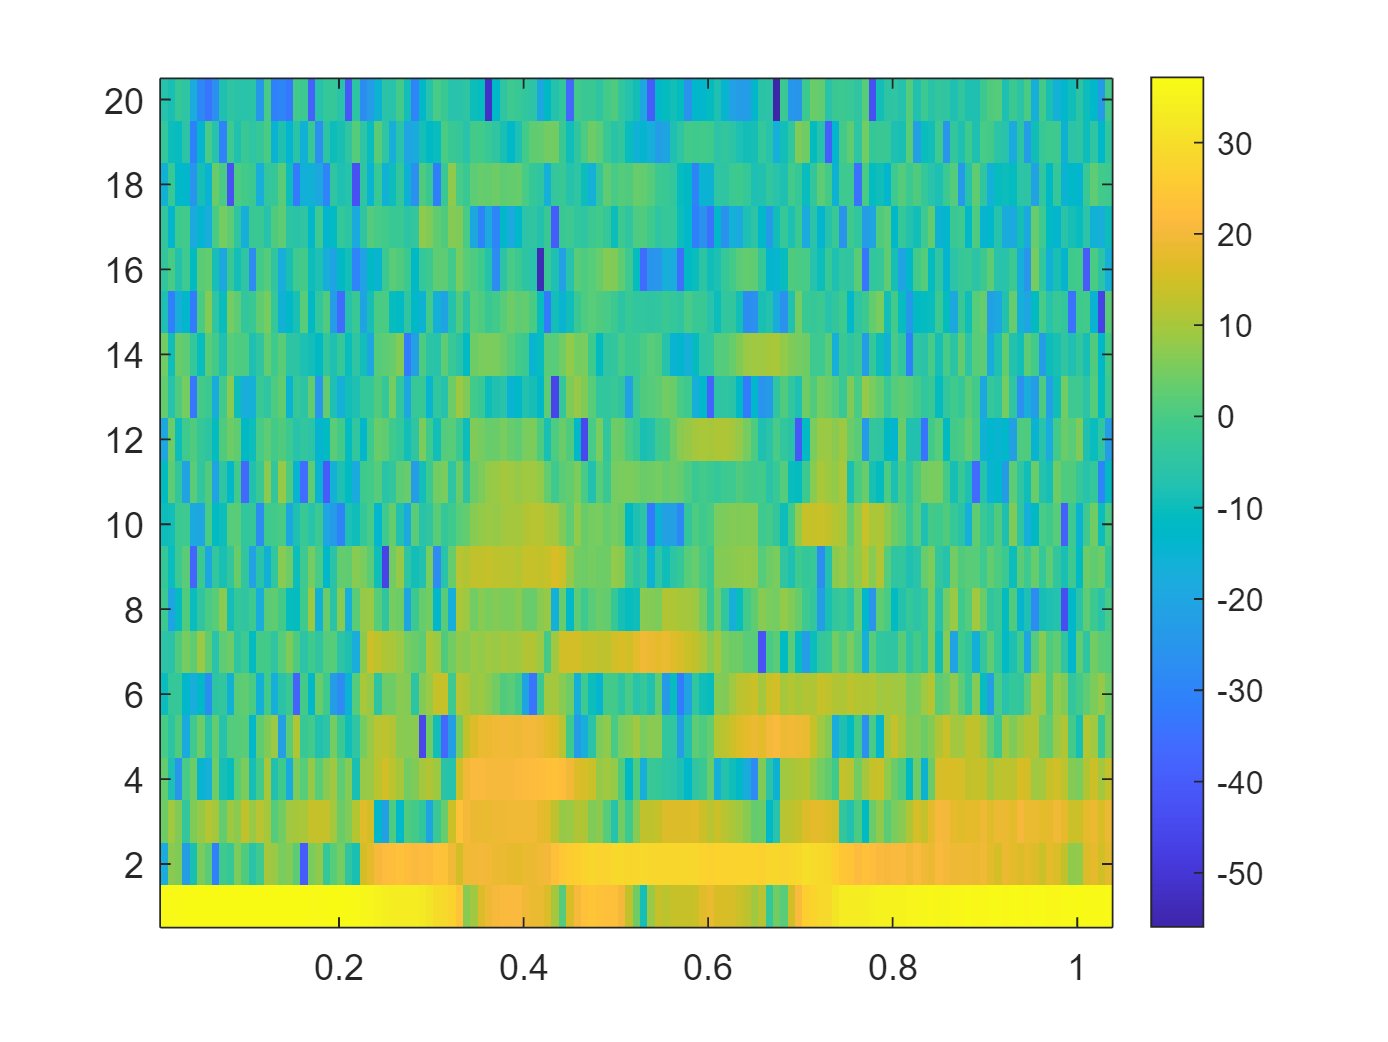

imagesc(T,(newf)',y);
set(gca, 'YDir', 'normal');
view(2)
colorbar

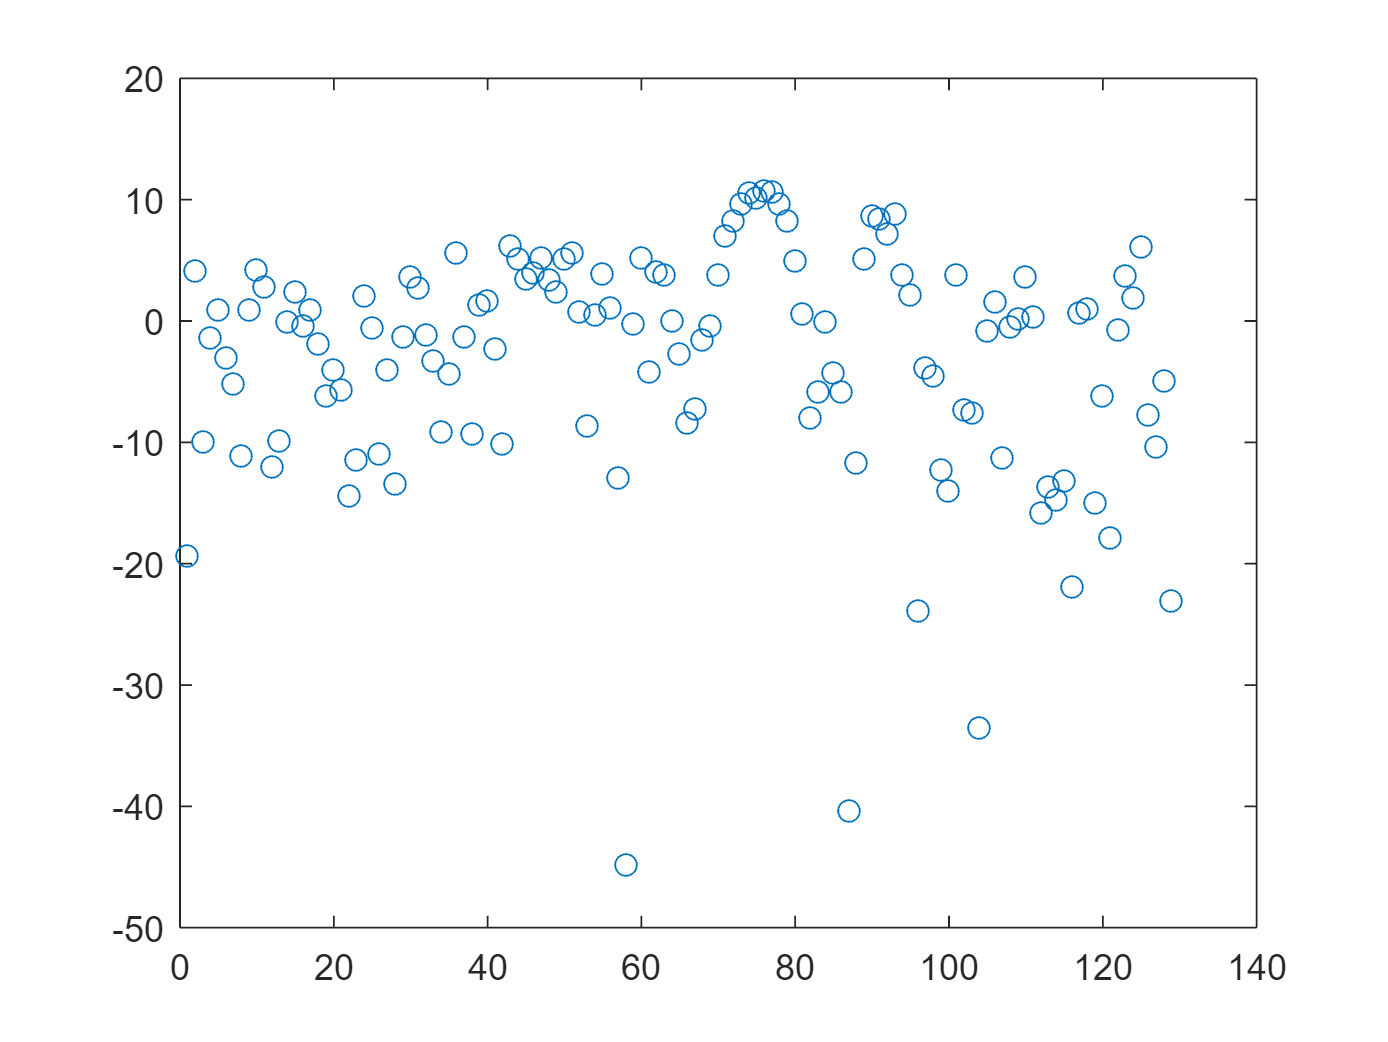

% end of dct part
plot(y(12,:),'o')

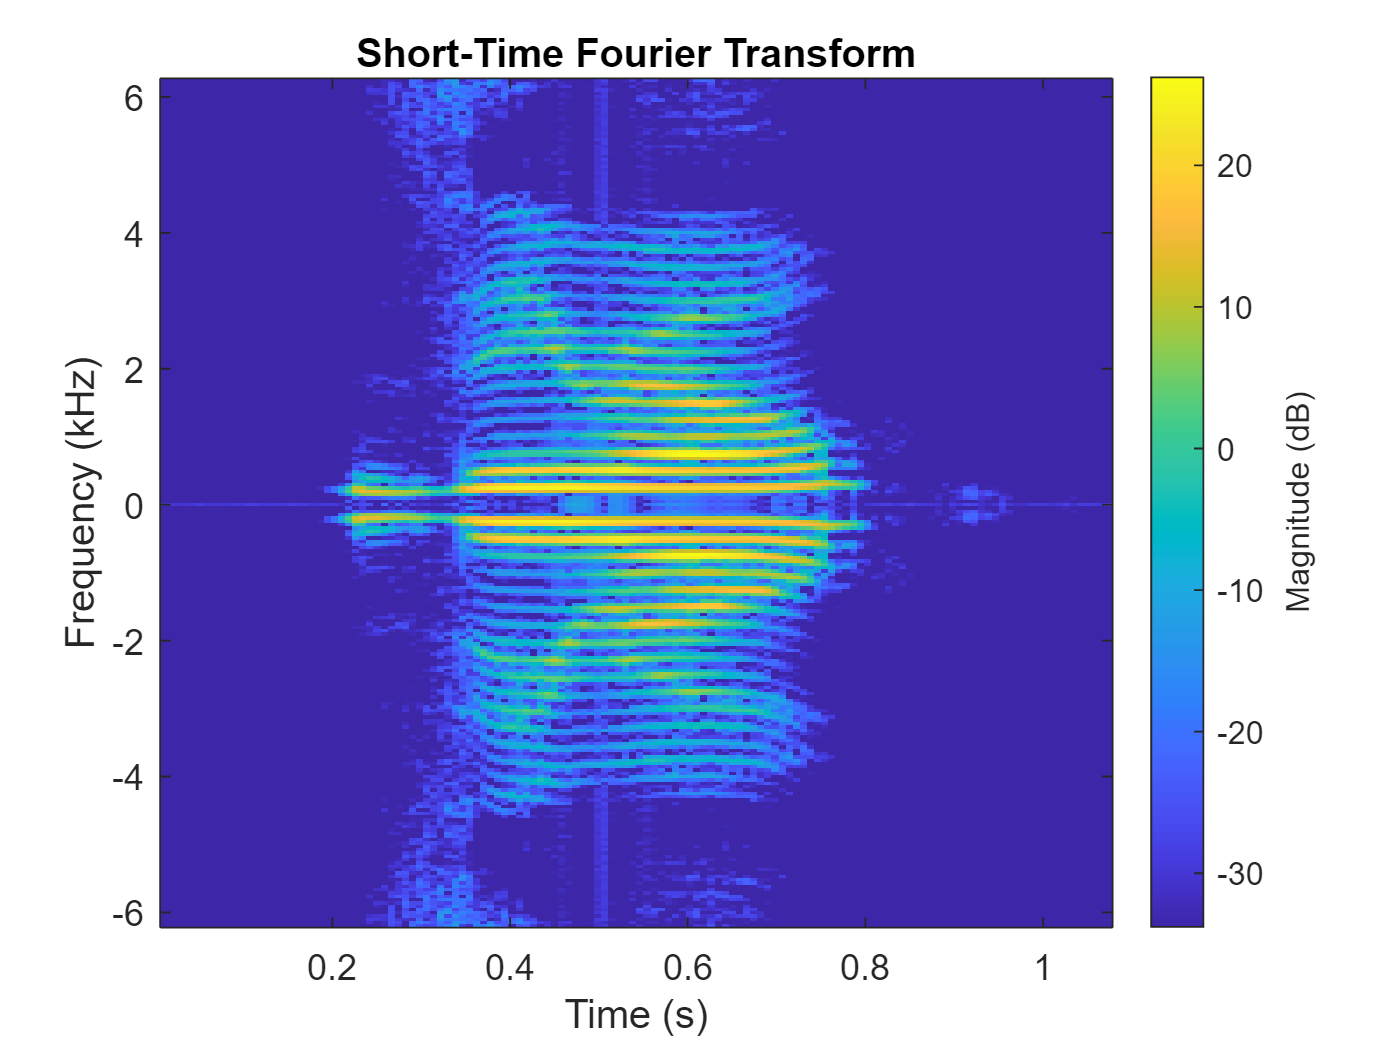

% s2
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s2.wav');
[S,F,T] = stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)

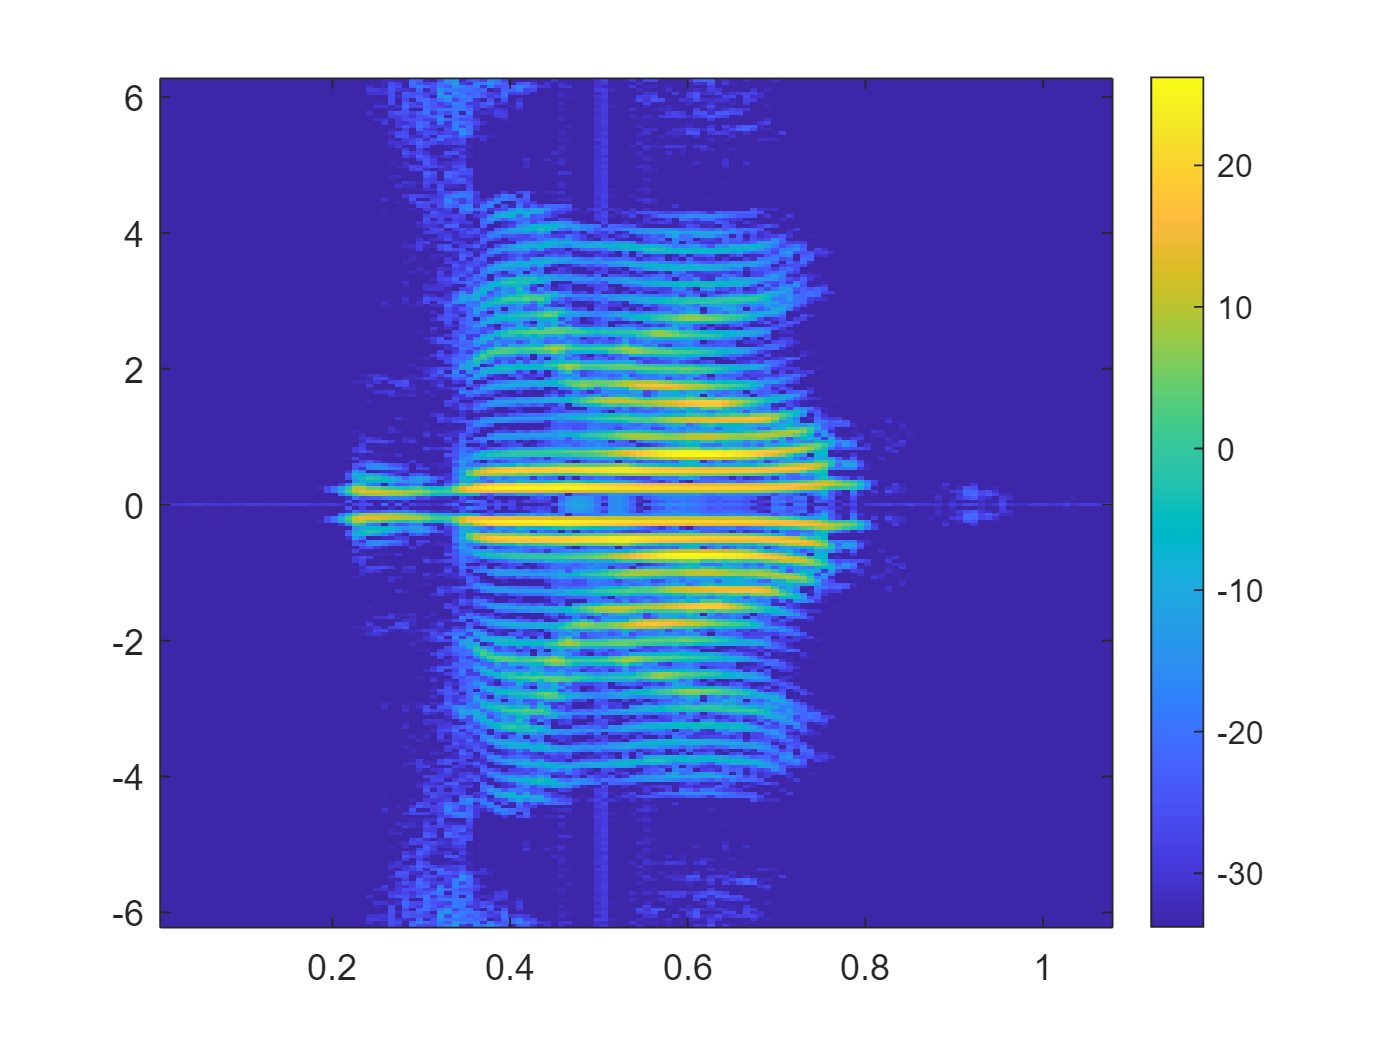

% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar

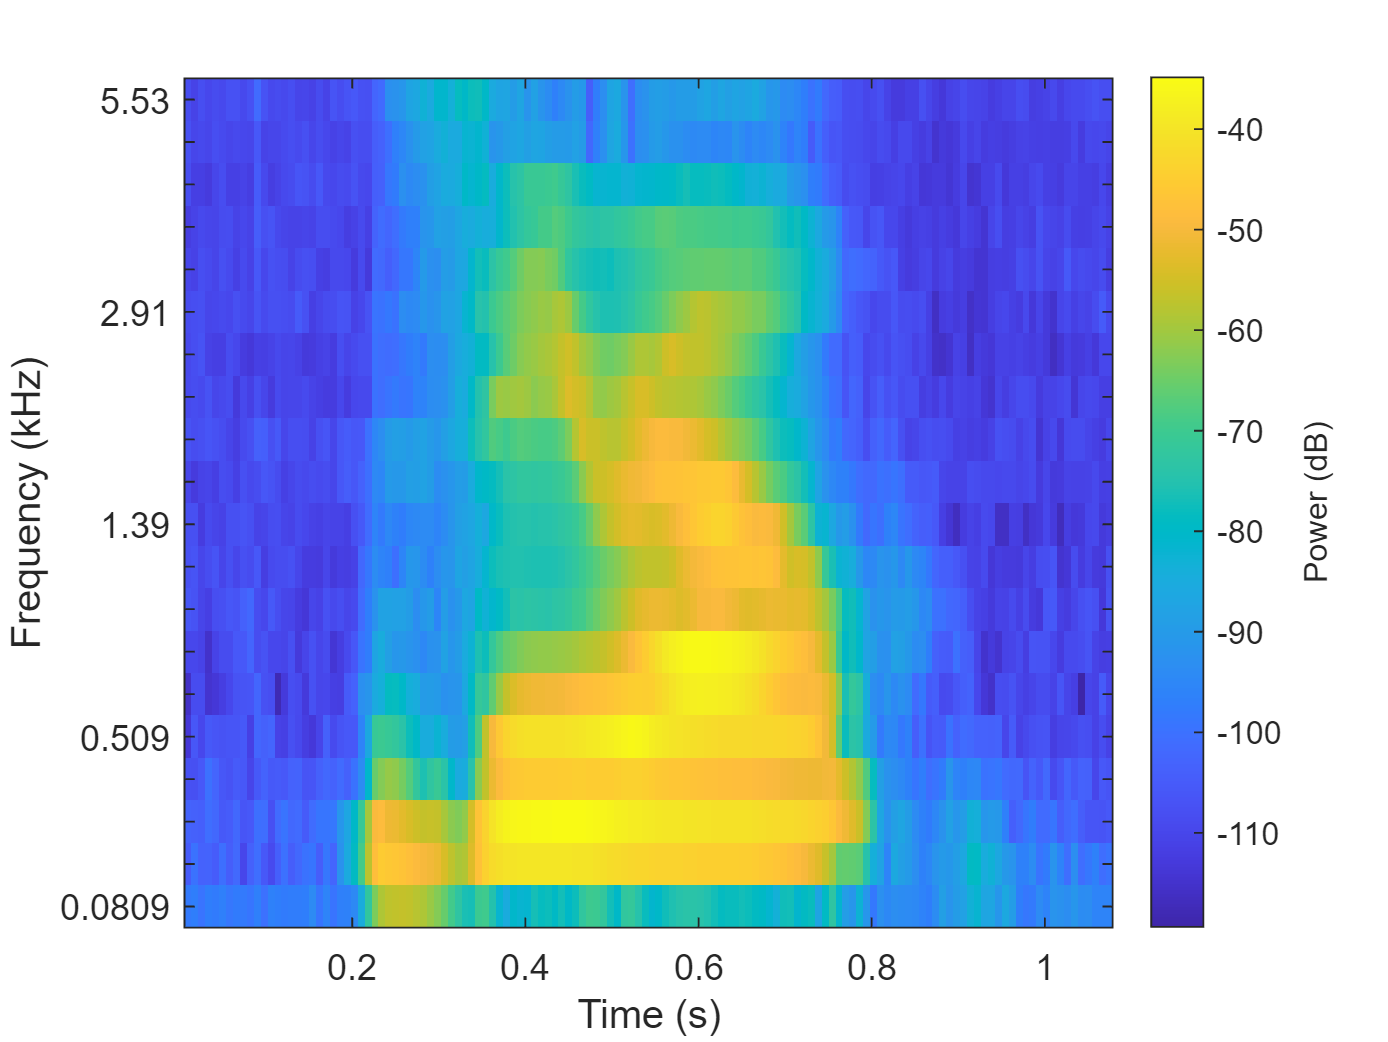

% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);

[Ss,Ff,Tt] = melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))

sdb1 =  -195.8431 -194.3462 -198.9452 -193.9975 -195.4545 -193.2564 -197.5499 -195.3467 -195.8906 -198.0744 -193.7027 -199.9293 -192.9433 -194.2263 -195.2141 -194.9746 -194.6685 -194.0999 -188.0024 -198.2067 -191.6930 -198.7231 -193.6176 -192.5985 -189.0796 -169.8774 -144.7957 -126.9678 -117.3599 -114.2728 -113.2843 -112.9530 -113.8798 -115.4526 -117.5135 -121.2006 -125.5983 -130.6811 -138.6314 -146.2592 -152.3661 -153.0983 -140.4850 -139.0215 -149.6907 -164.0837 -170.1779 -161.2031 -163.7268 -163.2568
 -209.4728 -199.6855 -206.8066 -205.8588 -209.2351 -200.9590 -208.9212 -203.4526 -219.6547 -207.3979 -201.6988 -211.1148 -218.1770 -208.2644 -200.3000 -208.3684 -203.7376 -199.6658 -198.2333 -208.6616 -197.1280 -205.5834 -184.0701 -170.9126 -158.0591 -137.7895 -114.8117  -96.2757  -90.7113  -91.9696  -92.4261  -93.9677  -95.8815  -97.9686  -99.8495 -101.0380 -103.2094 -108.5356 -114.5895 -118.1772 -117.1754 -107.2653  -95.0049  -87.7660  -84.0560  -81.7643  -80.3558  -79.7356  -79.4851  

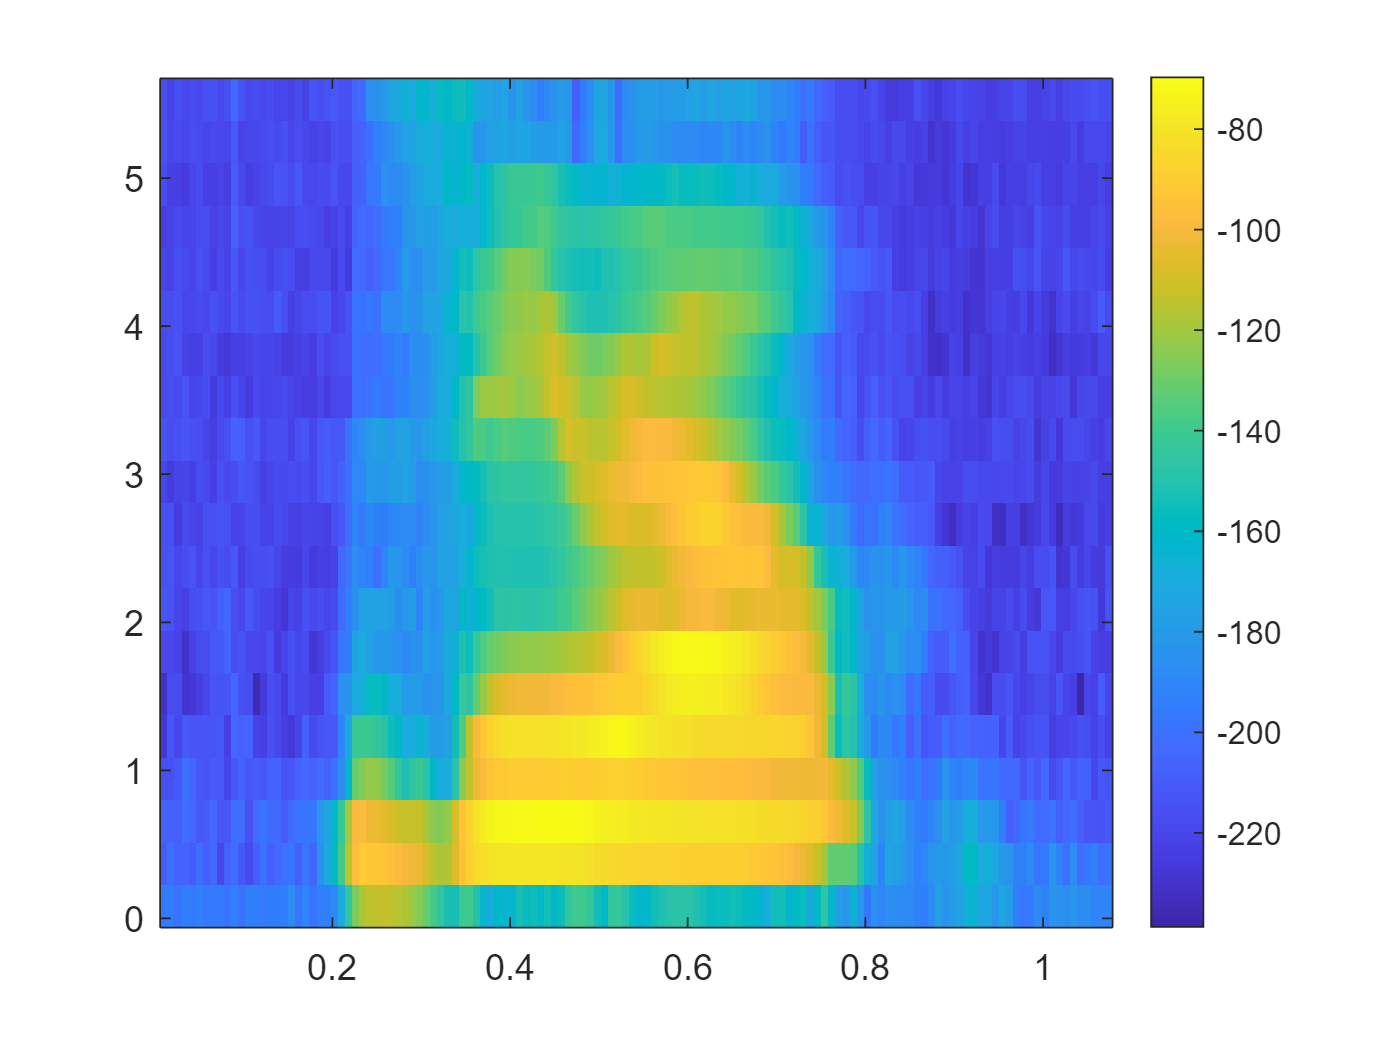

imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar

% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1))

bl =          0    1.6559  113.2620  128.0000



b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');

% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(n2-1:n)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some))

some =   -71.4316  -69.9744  -74.5258  -69.5778  -71.0749  -68.8856  -73.1315  -70.9284  -71.4650  -73.6635  -69.2805  -75.5092  -68.4996  -69.8033  -70.8314  -70.5429  -70.2485  -69.7365  -63.6154  -73.7978  -67.2763  -74.3324  -69.3100  -68.1819  -64.8454  -45.9384  -20.8488   -3.0418    6.5615    9.6482   10.6367   10.9685   10.0429    8.4703    6.4107    2.7226   -1.6767   -6.7581  -14.7085  -22.3325  -28.4364  -29.1554  -16.5473  -15.0381  -25.6765  -39.8464  -46.0627  -37.1866  -39.7759  -39.2177
  -84.2938  -74.4489  -81.6390  -80.6376  -84.0092  -75.6979  -83.7460  -78.2831  -94.3601  -82.2043  -76.5637  -86.0074  -93.0122  -83.0465  -75.1276  -83.2034  -78.6073  -74.4220  -73.0146  -83.5658  -72.0138  -80.3644  -58.9874  -45.8669  -33.0086  -12.7137   10.2721   28.7946   34.3924   33.1668   32.7190   31.1925   29.2874   27.2052   25.3225   24.1122   21.9235   16.6005   10.5366    6.9280    7.9087   17.7804   30.0130   37.2505   40.9256   43.1892   44.5831   45.1941   45.4404  

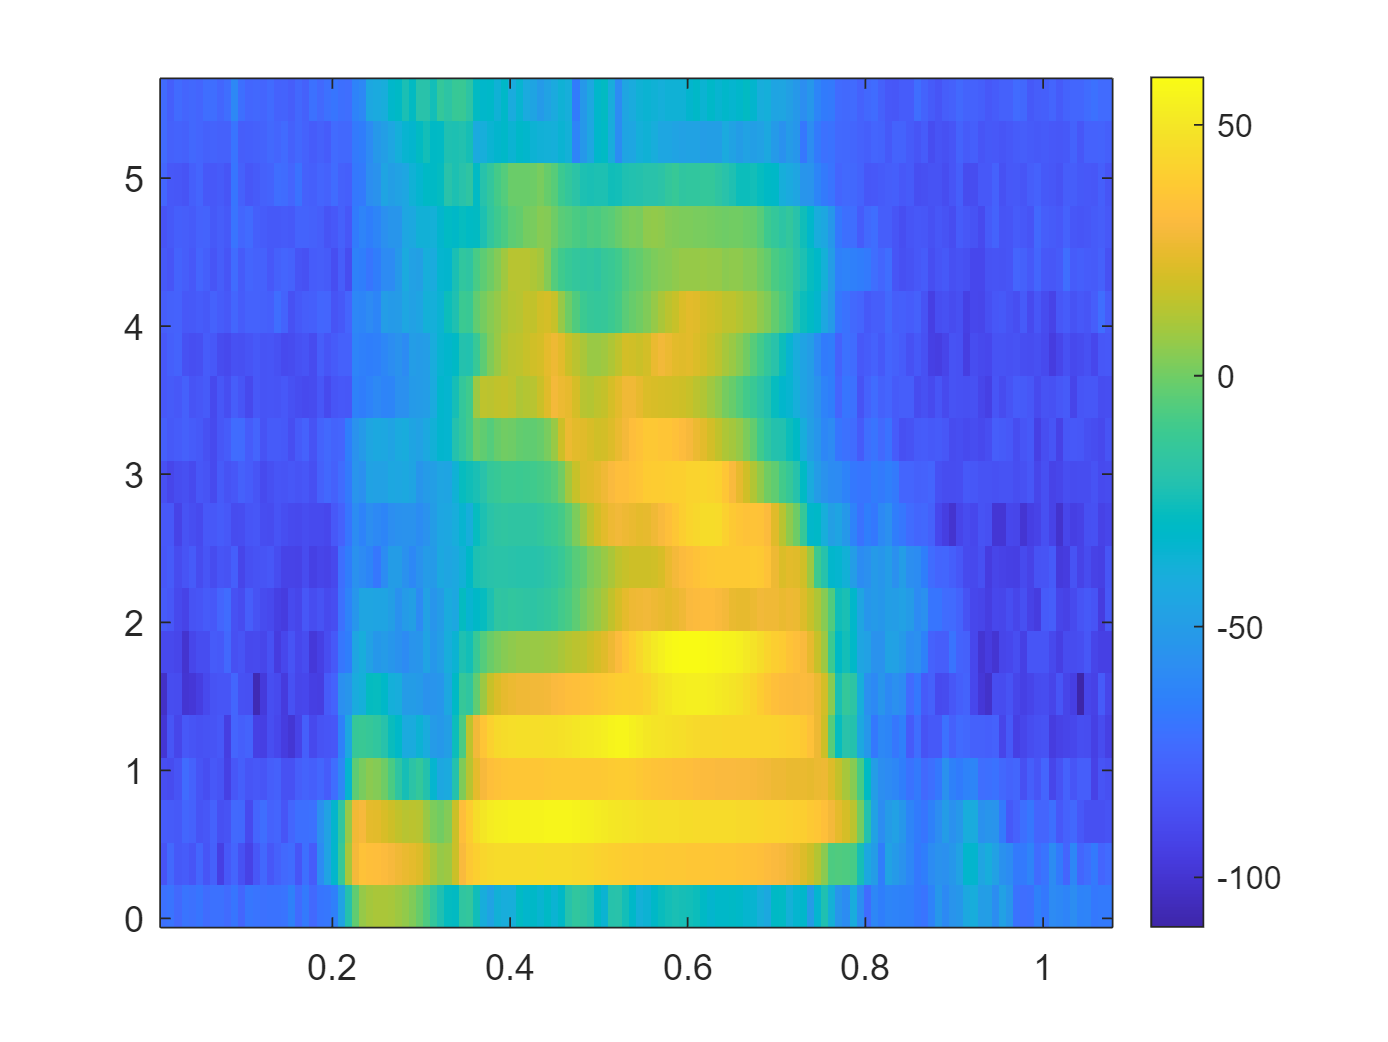

imagesc((T),(Ff/1000),some);
set(gca, 'YDir', 'normal');
view(2)
colorbar

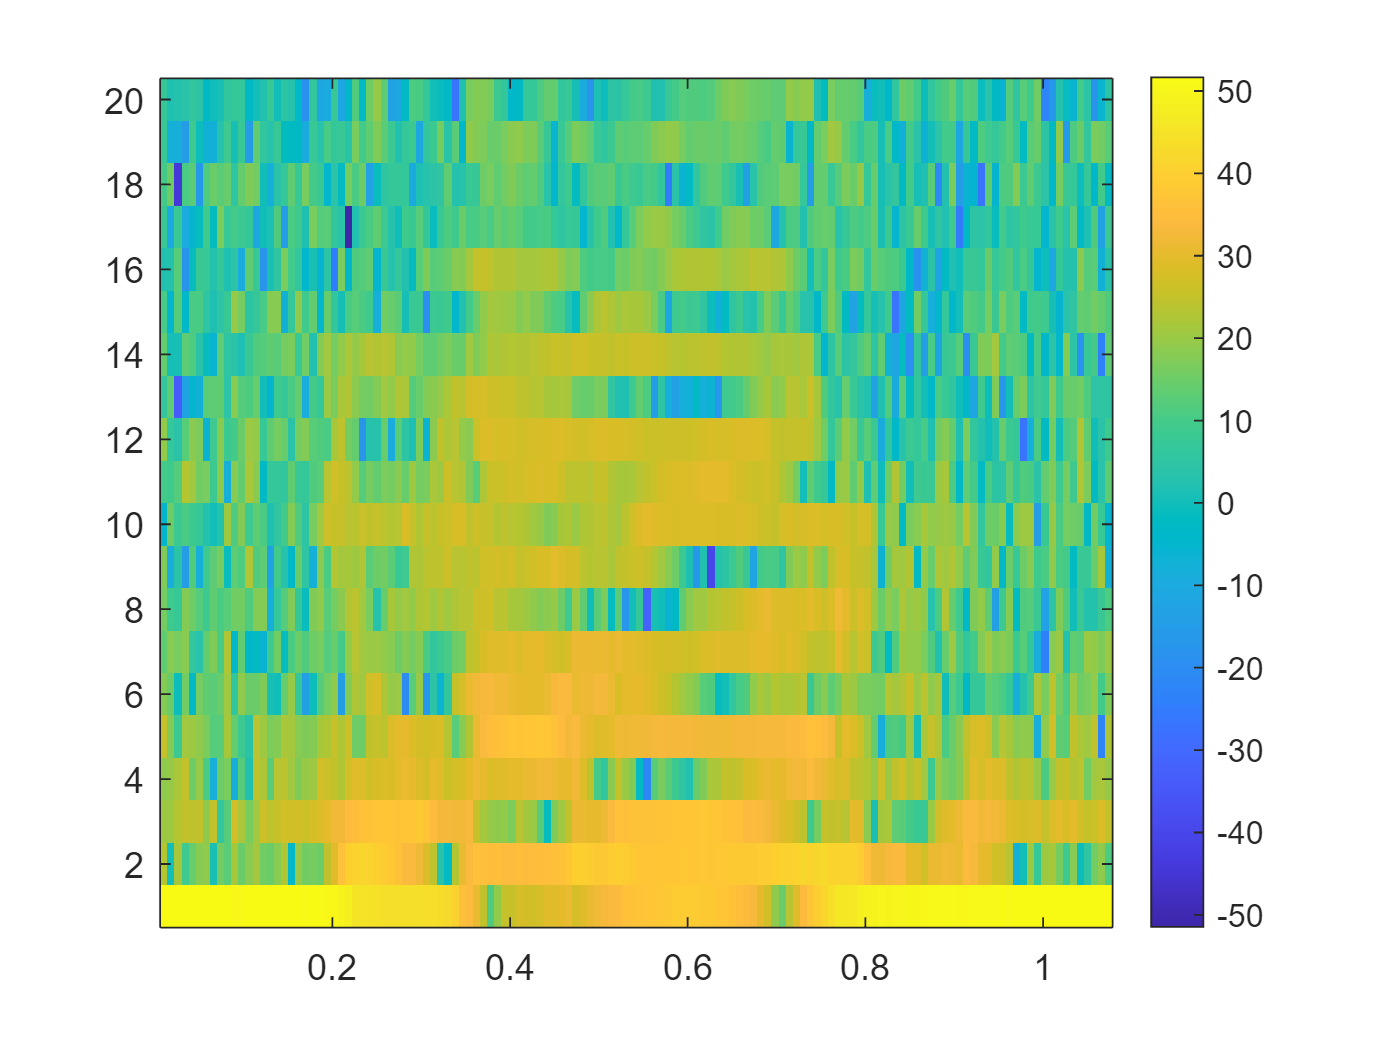

% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(some(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
imagesc(T,(newf)',sdb);
set(gca, 'YDir', 'normal');
view(2)
colorbar

% end of dct part

% s3
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s3.wav');
[S,F,T] = stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)
% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar
% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
[Ss,Ff,Tt] = melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1))

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');
% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(1:n2)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some))
imagesc((T),(Ff/1000),flip(some));
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(Ss(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
imagesc(T,(newf)',sdb);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of dct part

% s4
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s4.wav');
[S,F,T] = stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)
% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar
% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
[Ss,Ff,Tt] = melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1))

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');
% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(1:n2)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some))
imagesc((T),(Ff/1000),flip(some));
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(Ss(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
imagesc(T,(newf)',sdb);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of dct part

% s5
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s5.wav');
[S,F,T] = stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)
% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar
% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
[Ss,Ff,Tt] = melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1))

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');
% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(1:n2)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some))
imagesc((T),(Ff/1000),flip(some));
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(Ss(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
imagesc(T,(newf)',sdb);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of dct part

% s6
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s6.wav');
[S,F,T] = stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)
% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar
% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
[Ss,Ff,Tt] = melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1))

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');
% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(1:n2)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some))
imagesc((T),(Ff/1000),flip(some));
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(Ss(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
imagesc(T,(newf)',sdb);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of dct part

% s7
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s7.wav');
[S,F,T] = stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)
% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar
% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
[Ss,Ff,Tt] = melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1))

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');
% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(1:n2)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some))
imagesc((T),(Ff/1000),flip(some));
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(Ss(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
imagesc(T,(newf)',sdb);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of dct part

% s8
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s8.wav');
[S,F,T] = stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)
% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar
% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
[Ss,Ff,Tt] = melSpectrogram(y1,Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1))

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');
% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(1:n2)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some))
imagesc((T),(Ff/1000),flip(some));
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(Ss(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
imagesc(T,(newf)',sdb);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of dct part

% s9
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s9.wav');
[S,F,T] = stft(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)
% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar
% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
[Ss,Ff,Tt] = melSpectrogram(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1))

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');
% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(1:n2)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some))
imagesc((T),(Ff/1000),flip(some));
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(Ss(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
imagesc(T,(newf)',sdb);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of dct part

% s10
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s10.wav');
[S,F,T] = stft(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)
% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar
% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
[Ss,Ff,Tt] = melSpectrogram(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1))

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');
% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(1:n2)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some))
imagesc((T),(Ff/1000),flip(some));
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(Ss(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
imagesc(T,(newf)',sdb);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of dct part

% s11
% reading audio and doing framing, overlap, windowing, and fft
[y1,Fs1] = audioread('GivenSpeech_Data\Training_Data\s11.wav');
[S,F,T] = stft(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256);
% end of framing, overlap, windowing, and fft

% plotting using function
stft(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256)
% end of plotting using function

% manually plotting above graph
sdb = mag2db(abs(S));
imagesc(T,F/1000,sdb);
cc = max(sdb(:))+[-60 0];
ax = gca;
set(gca, 'YDir', 'normal');
ax.CLim = cc;
view(2)
colorbar
% end of manually plotting above graph

% mel spectrogram graph what we want
melSpectrogram(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
[Ss,Ff,Tt] = melSpectrogram(y1(:,1),Fs1,Window=hamming(256,'periodic'),OverlapLength=156,FFTLength=256,NumBands=20);
sdb1 = mag2db(abs(Ss))
imagesc(Tt,Ff/1000,sdb1);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of mel spectrogram graph

% melfb part
p = 20;
n = 256;
fs = Fs1;
f0 = 700 / fs;
fn2 = floor(n/2);

lr = log(1 + 0.5/f0) / (p+1);

% convert to fft bin numbers with 0 for DC term
bl = n * (f0 * (exp([0 1 p p+1] * lr) - 1))

b1 = floor(bl(1)) + 1;
b2 = ceil(bl(2));
b3 = floor(bl(3));
b4 = min(fn2, ceil(bl(4))) - 1;

pf = log(1 + (b1:b4)/n/f0) / lr;
fp = floor(pf);
pm = pf - fp;

r = [fp(b2:b4) 1+fp(1:b3)];
c = [b2:b4 1:b3] + 1;
v = 2 * [1-pm(b2:b4) pm(1:b3)];

m = sparse(r, c, v, p, 1+fn2);

plot(linspace(0, (12500/2), 129), (m)');
title('Mel-spaced filterbank'), xlabel('Frequency (Hz)');
% end of melft part

% applying melfb m value
[rows,cols] = size(S);
for i = 1:cols
    f = S(:,i);
    n2 = 1 + floor(n/2);
    z = m * abs(f(1:n2)).^2;
    if i == 1
        some = [z];
    else
        some = [some z];
    end
end
some = mag2db(abs(some))
imagesc((T),(Ff/1000),flip(some));
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of applying melfb m value

% dct part
for i = 1:cols
    f = dct(Ss(:,i));
    if i == 1
        y = [f];
    else
        y = [y f];
    end
end
sdb = mag2db(abs(y));
newf = 1:1:20;
imagesc(T,(newf)',sdb);
set(gca, 'YDir', 'normal');
view(2)
colorbar
% end of dct part